# Neuropixels Toolkit Live Script

## Build and execute a processing session with pipelines

### Setup Logger

import npxtoolkit.internal.thirdparty.logging.log4m
logger = log4m.getLogger("npx.log");
logger.clearLog();
logger.setLogLevel(logger.DEBUG);

### Processing Session

import npxtoolkit.session.Session
import npxtoolkit.pipeline.Pipeline
import npxtoolkit.internal.config.Config
% define session
session = Session('Session Info');

### Setup Python Env

PYENV_PATH = '/home/ubuntu/anaconda3/envs/npx/bin/python';
session.setPyEnv(PYENV_PATH);
% init session by pipelines, stages and jobs

### Method 1 - Auto-assembled pipeline

%% Auto-assembled pipeline
pipeline = Pipeline('Pipeline0 Info', "configs/test_config.json");
pipeline.autoAssemble();
session.addPipeline(pipeline);
session.parExecute();

### Method 2 - Manually-assmubled pipeline

import npxtoolkit.pipeline.Pipeline
import npxtoolkit.stage.Stage
import npxtoolkit.tasks.CatGT
import npxtoolkit.tasks.KiloSort
import npxtoolkit.tasks.TPrime

%% Pipeline 1
pipeline1 = Pipeline('Pipeline0 Info', "configs/test_config.json");

% CatGT stage
stageCatgt = Stage('CatGT');
pipeline1.addStage(stageCatgt);
% CatGT task 1
taskCatgt1 = CatGT('CatGT probe 0', '0', 1, pipeline1.PipelineConfigs);
stageCatgt.addTask(taskCatgt1);

% KiloSort stage
stageKilo = Stage('KiloSort');
pipeline1.addStage(stageKilo);
% KiloSort task 1
taskKilo1 = KiloSort('KiloSort probe 0', '0', 'cortex', pipeline1.PipelineConfigs);
stageKilo.addTask(taskKilo1);

% TPrime stage
stageTPrime = Stage('TPrime');
pipeline1.addStage(stageTPrime);
% TPrime task 1
taskTPrime1 = TPrime('TPrime probe 0', '0', pipeline1.PipelineConfigs);
stageTPrime.addTask(taskTPrime1);

% append pipeline to session
session.addPipeline(pipeline1);
%% Execution
session.parExecute();

### Single Task Execution for testing or debugging

import npxtoolkit.internal.config.PipelineConfig
import npxtoolkit.tasks.CatGT
import npxtoolkit.tasks.KiloSort
import npxtoolkit.tasks.TPrime

pipelineConfig = PipelineConfig("configs/test_config.json");
task = CatGT('CatGT probe 0', '0', 1, pipelineConfig);
% config = TaskConfig(json.KiloSort);
% task = KiloSort('KiloSort probe 0', '0', 'cortex', pipelineConfig);
% config = TaskConfig(json.TPrime);
% task = TPrime('TPrime probe 0', '0', pipelineConfig);
task.execute();

## Visualization Examples

These are currently not included in the Neuropixels-toolkit package, just to demonstrate the pipeline's results.

Data files are coming from the data directory in the config json file config["data"], in this case, they are in: `/home/ubuntu/neuropixel/data_for_ecephys/subject1_session1/catgt_SC011_021919_g0/SC011_021919_g0_imec0/imec0_ks2`

% this is the same as config["pipeline"]["tools"]["npyMatlabRepo"]
addpath('/home/ubuntu/neuropixel/npy-matlab/npy-matlab/'); 
addpath('.');

### Mean Waveforms

meanWaveforms = readNPY('./test_data/mean_waveforms.npy');
disp(size(meanWaveforms));
samplingRate = 29999.9
one_unit = squeeze(meanWaveforms(2,:,:))';
plot((0:size(one_unit, 1)-1)/samplingRate*1000, one_unit);

   275   301    82



title('Mean Waveforms');

samplingRate = 3.0000e+04

xlabel('Time(ms)');
ylabel('Amp');

### Spike Time

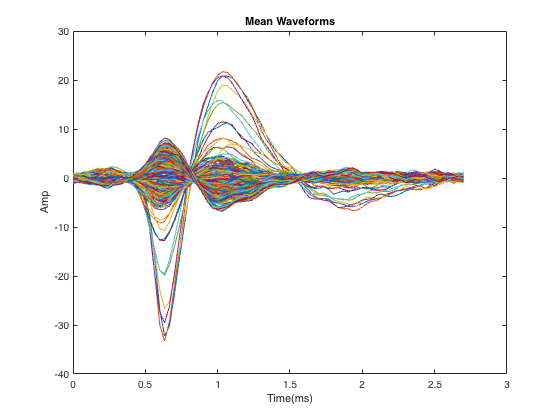

spikeTime = readNPY('./test_data/spike_times.npy');
disp(size(spikeTime));
spikeCluster = readNPY('./test_data/spike_clusters.npy');

disp(size(spikeCluster));
scatter(spikeTime(1:10000:7971090), spikeCluster(1:10000:7971090));
title('Spike Time vs Spike Clusters downsampled by 10000');

     7971090           1



     7971090           1



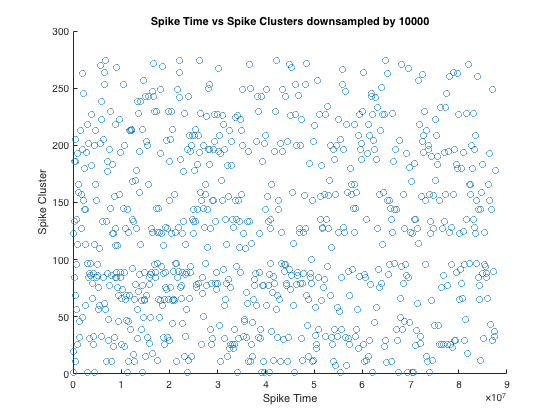

xlabel('Spike Time');
ylabel('Spike Cluster');